Section 1.0.0 - initial pipeline entry
Section 1.1.0 - Load image


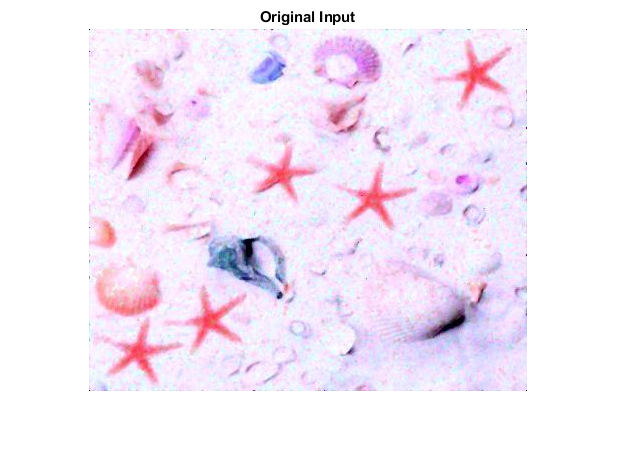

Section 1.2.0 - Median Filter
Section 1.2.1 - Mean filter on salty channels


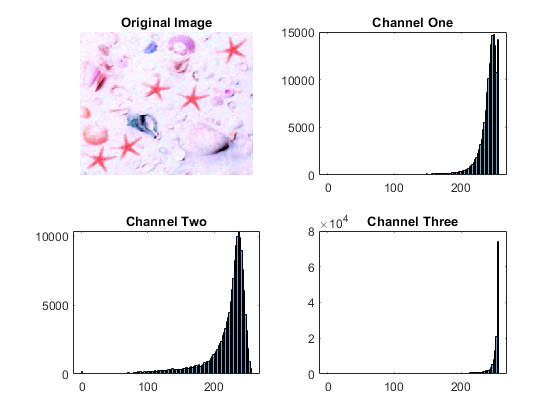

red Channel salt and pepper noise
Blue Channel Salt and Pepper Noise


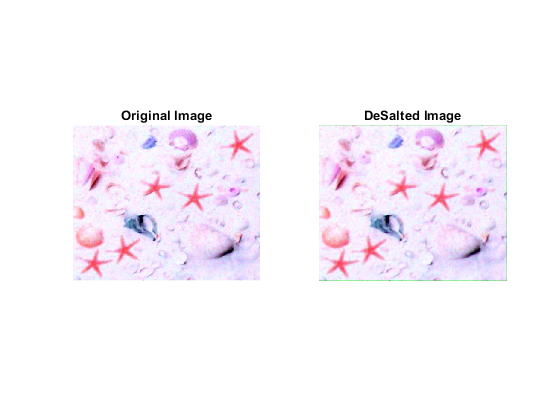

Section 1.3.0 - Convert to HSV for analysis of saturation, hue and values


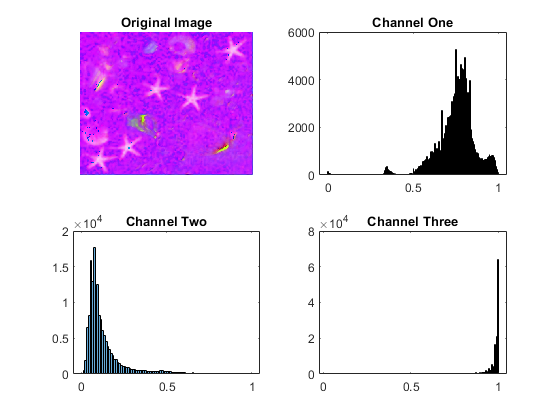

Section 1.4.0 - Saturize the image, drawing lots of contrast between the bright and dark colours


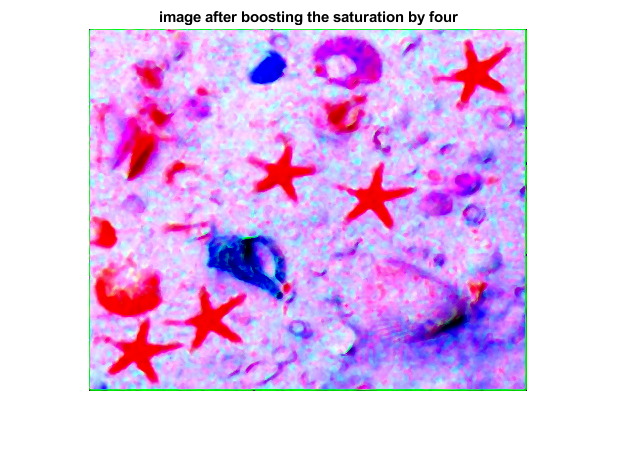

Section 1.5.0 - unsharp the image


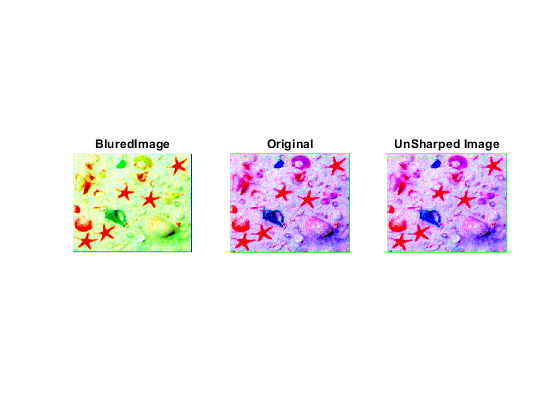

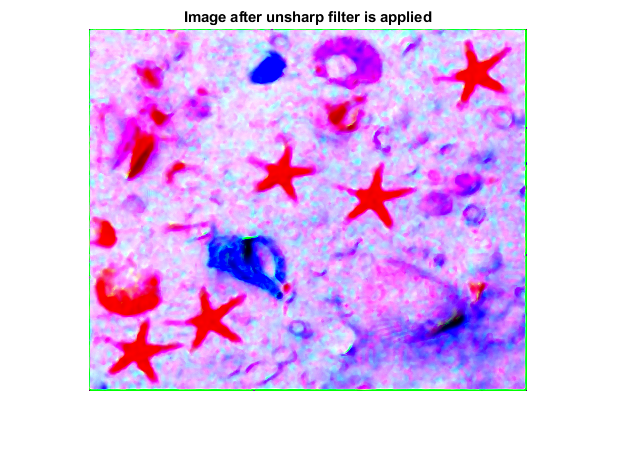

Section 1.6.0 -  Gather the bin counts of each channel after saturation


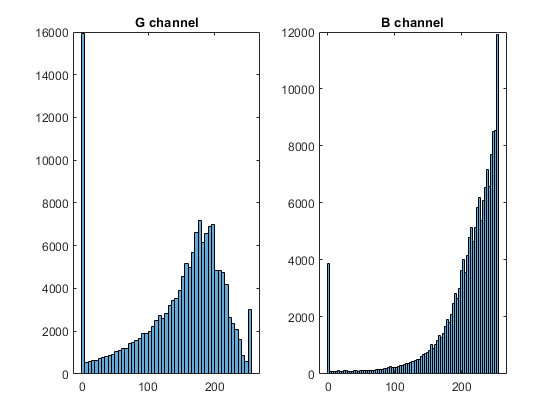

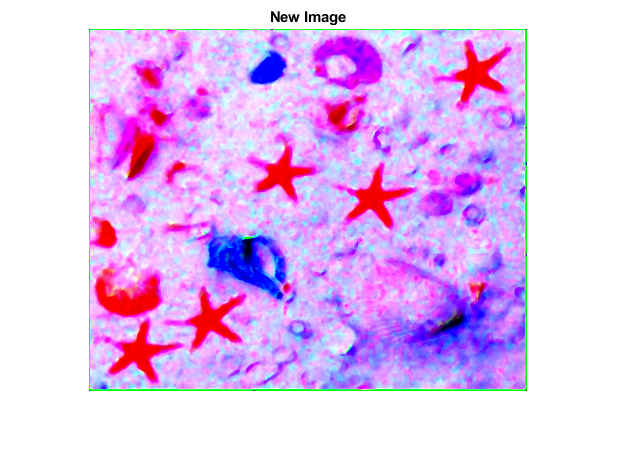

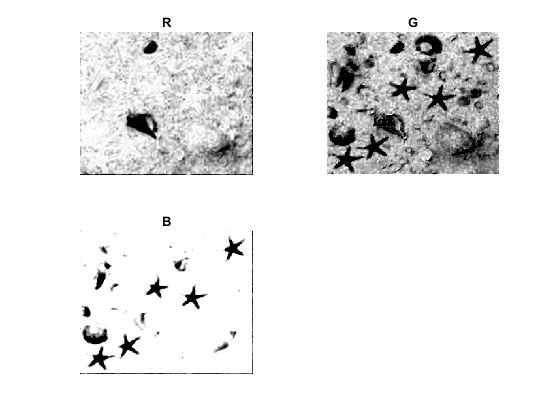

Section 1.6.1 - comparing the chanels for thier noise
Taking Green Channel


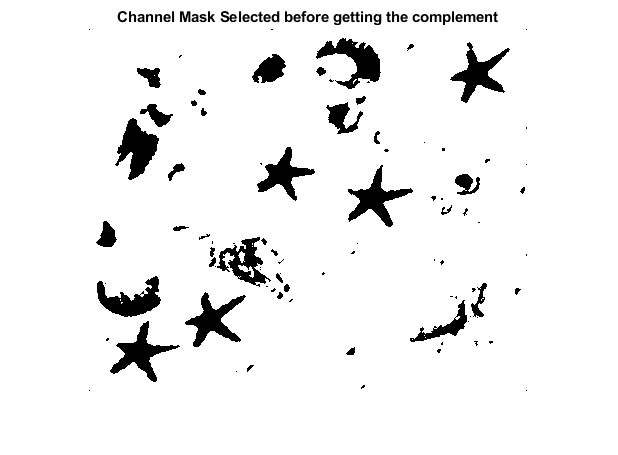

Section 1.6.2 - Take the complement if the number of positive values in the binary mask is greater then the number of zeros
Getting the complement
Section 1.7.0 - Morphology


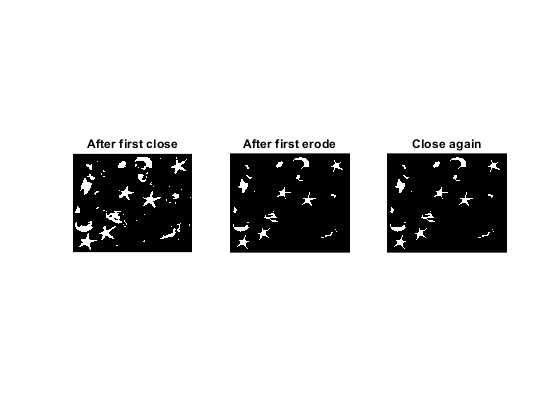

Section 2.0.0 - post pipeline cleanup
Section 2.1.0 - Remove huge and tiny objects


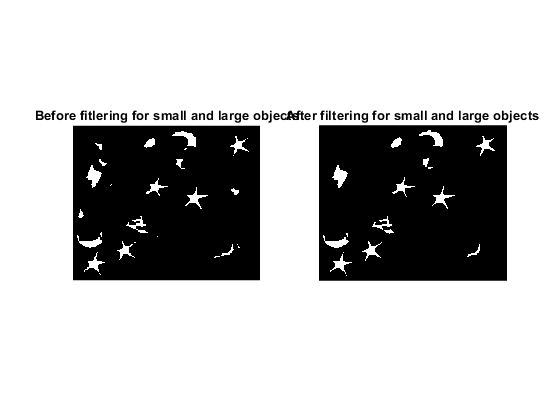

Section 2.2.0 - Active Contouring


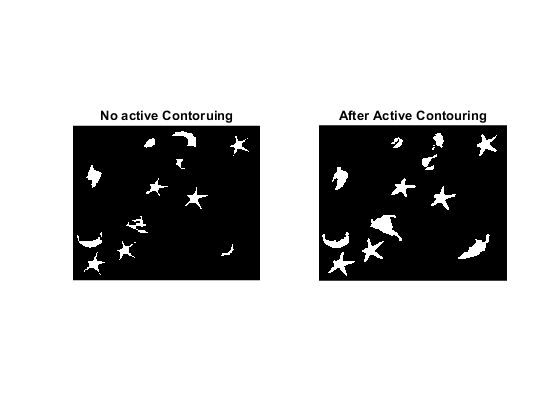

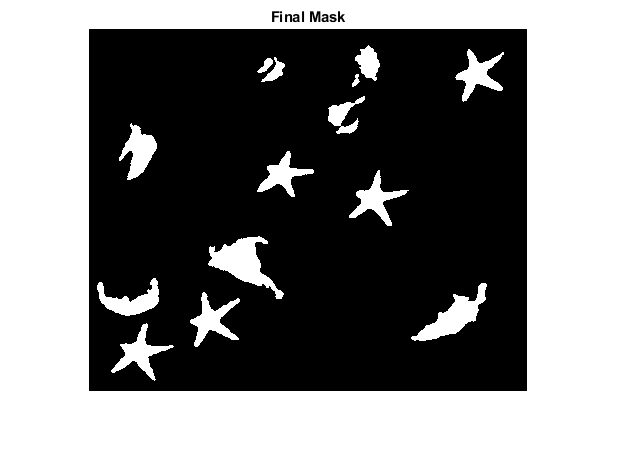

Section 3.0.0 - MSER region analysis one
Section 3.1.0 - MSER Regions


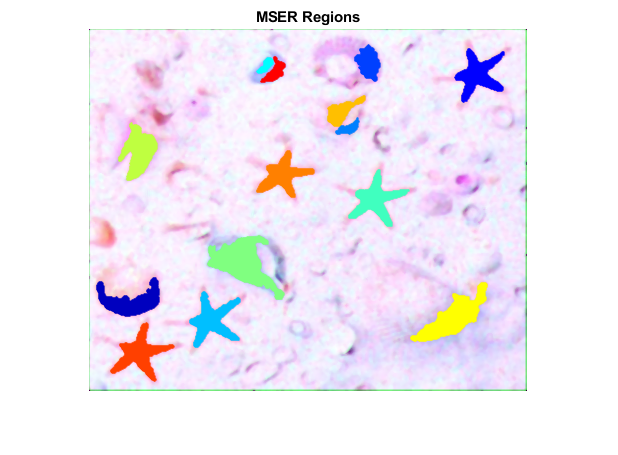

Section 3.2.0 - initial filtering
1: BoudningBox:  X: 366.5 Y: 20.5 Eccentricity: 0.51737 Solidity: 0.50423 Area: 1013
2: BoudningBox:  X: 260.5 Y: 141.5 Eccentricity: 0.50216 Solidity: 0.48174 Area: 1016
3: BoudningBox:  X: 168.5 Y: 122.5 Eccentricity: 0.71555 Solidity: 0.55276 Area: 901
4: BoudningBox:  X: 101.5 Y: 263.5 Eccentricity: 0.49135 Solidity: 0.46619 Area: 1041
5: BoudningBox:  X: 22.5 Y: 294.5 Eccentricity: 0.57369 Solidity: 0.46451 Area: 1047


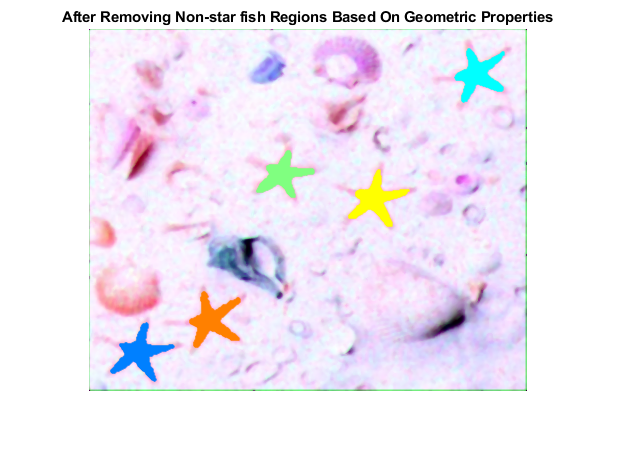

%Test Single File
fileLocation = "./workingImages/starfish_map1.jpg";
[boundingBoxes,NoStarfish] = masterPipeline(fileLocation);

sizeOfBoudingBox = size(boundingBoxes);
output = figure;
imshow(fileLocation);
hold on;
for x = 1:sizeOfBoudingBox(1)
    
  thisBB = boundingBoxes(x, (1:4));
  text(thisBB(1) + thisBB(3) /2, thisBB(2) - 10,"" + x);
  rectangle('Position', [thisBB(1),thisBB(2),thisBB(3),thisBB(4)],'EdgeColor','r','LineWidth', 2);
    

end
hold off;
title("Final Output: There are " + NoStarfish + " Starfish");
mkdir("./" + NoStarfish + "/");

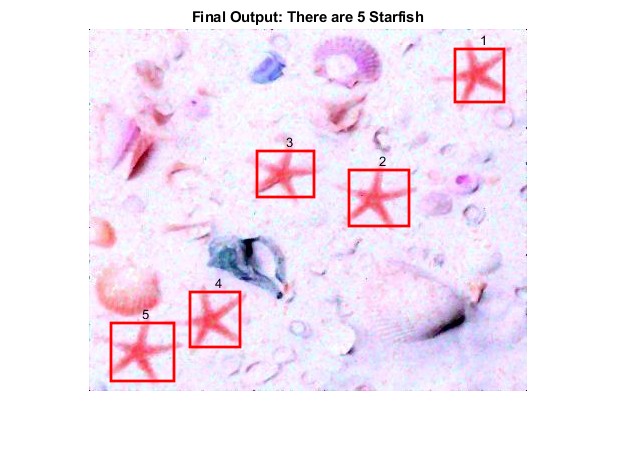

saveas(output, "./" + NoStarfish + "/" + "Test.jpg");